# Single Sine Excitation of a Nonlinear Activation Unit: Arbitrary Gain Signals

# Simplifying the Mu Function

Mauro J. Sanchirico III

## Setup

clc; clear; close all;

A nonlinear activation unit with input gain $\gamma \text{\,}$ is defined:


$$\varphi \text{\,}\left(v\right)=tanh\left(\gamma \text{\,}v\right)$$


For input signal $v=sin\left(\omega t+\phi \text{\,}\right)$ we wish to know the Fourier Series of the output signal $y=\varphi \text{\,}\left(v\right)$

That is we want to know the Fourier Series of:


$$y\left(t\right)=tanh\left(\gamma \text{\,}sin\left(\omega t+\phi \text{\,}\right)\right)$$


Or more simply:


$$y\left(x\right)=\text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right),\text{\,}x=\omega t+\phi$$


When the input gain is restricted to $|\gamma \text{\,}|<\frac{\pi }{2}$, the following expression can be derived via straightforward Taylor series expansion, the power reduction formula for trigonometric polynomials, and series manipulations:


$$\text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right)$$

$$=\text{\,}\sum_{n=1}^{\infty } \sum_{m=n}^{\infty \text{\,}} \frac{{\left(-1\right)}^{2m-n-1} 4\left(2^{2m} -1\right)\gamma^{2m-1} C_{m-n}^{2m-1} B_{2m} }{\left(2m\right)!}\text{\,}sin\left(\left(2n-1\right)x\right)$$


Now we desire a more powrful expression for the Fourier Series of $\text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right)$ valid for all $\gamma >0$.

Such an expression is given in the manuscript "Single Sine Excitation of a Nonlinear Activation Unit: Arbitrary Gain Signals" (Sanchirico 2019):


$$tanh\left(\gamma \text{\,}sin\left(x\right)\right)=\frac{2}{\pi \text{\,}}\sum_{n=1}^{\infty } \left\lbrace \frac{2}{2n-1}+\sum_{m=1}^{\infty } \sum_{l=0}^{\infty } \frac{{\left(-1\right)}^{m+l} 2^{l+1} m^l }{l!}{\text{\,}\gamma }^l \text{\,}\int_0^{\pi } sin\left(\left(2n-1\right)\text{\,}x\right){sin}^l \left(x\right)dx\right\rbrace sin\left(\left(2n-1\right)x\right)$$


This expression contains a function which was not intergrable analytically using MATLAB, Maple, online tools, etc, and I was not able to find it in any integration tables:


$$\mu \text{\,}\left(n,l\right)=\int_0^{\pi \text{\,}} sin\left(\left(2n-1\right)x\right){sin}^l \left(x\right)dx\text{\,\,\,}\forall n,l\in 0,1,\ldotp \ldotp \ldotp$$


Not only does there seem to be no readily available analytic integration rule, but numerical computation of this integral is difficult and requires a very small step size, and thus great computational expense to perform accurately.

We therefore wish to break down and simplify this special function, with the goal of identifying an efficient and effective means of computing it.

## Breaking up the inner sum

We begin by breaking up the inner sum in the expansion of $tanh\left(\gamma \text{\,}sin\left(x\right)\right)$ into even and odd sums.  We use a shorthand $q\left(m,l\right)$ for the quotient inside the $l$ summation.


$$tanh\left(\gamma \text{\,}sin\left(x\right)\right)=\frac{2}{\pi }\sum_{n=1}^{\infty } \left\lbrace \frac{2}{2n-1}+\sum_{m=1}^{\infty } \sum_{l=0}^{\infty } q\left(m,l\right)\mu \text{\,}\left(n,l\right)\gamma^l \right\rbrace sin\left(\left(2n-1\right)x\right)$$



$$\text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right)=\frac{2}{\pi }\sum_{n=1}^{\infty } \left\lbrace \frac{2}{2n-1}+\sum_{m=1}^{\infty } \left(\sum_{l=0}^{\infty } q\left(m,2l\right)\mu \text{\,}\left(n,2l\right)\gamma^{2l} +\sum_{l=0}^{\infty } q\left(m,2l+1\right)\mu \text{\,}\left(n,2l+1\right)\gamma^{2l+1} \right)\right\rbrace \sin \left(\left(2n-1\right)x\right)$$


## The even mu function

Here we break up the even mu function by applying a power reduction formula.


$$\mu \text{\,}\left(n,2l\right)=\int_0^{\pi \text{\,}} sin\left(\left(2n-1\right)x\right){sin}^{2l} \left(x\right)dx$$


Expanding $\sin^{2l} \left(x\right)$ using rule 1.320.1 on page 31 of Gradsteyn and Rhyzik (pg 31 - page 80 in the PDF):


$${sin}^{2l} \left(x\right)=\frac{1}{2^{2l} }\left\lbrace \sum_{k=0}^{l-1} {\left(-1\right)}^{l-k} 2{\text{\,}C}_k^{2l} cos\left(2\left(l-k\right)x\right)+C_l^{2l} \right\rbrace$$



$$\mu \text{\,}\left(n,2l\right)=\int_0^{\pi \text{\,}} \sin \left(\left(2n-1\right)x\right)\frac{1}{2^{2l} }\left\lbrace \sum_{k=0}^{l-1} {\left(-1\right)}^{l-k} 2{\text{\,}C}_k^{2l} cos\left(2\left(l-k\right)x\right)+C_l^{2l} \right\rbrace \text{dx}$$


Distributing the term $\sin \left(\left(2n-1\right)x\right)$ and moving the $\frac{1}{2^{2l} }$ term outside of the integral:


$$\mu \text{\,}\left(n,2l\right)=\frac{1}{2^{2l} }\int_0^{\pi \text{\,}} \left\lbrace \sum_{k=0}^{l-1} {\left(-1\right)}^{l-k} 2{\text{\,}C}_k^{2l} \sin \left(\left(2n-1\right)x\right)\cos \left(2\left(l-k\right)x\right)+C_l^{2l} \sin \left(\left(2n-1\right)x\right)\right\rbrace \text{dx}$$


Rearranging:


$$\mu \text{\,}\left(n,2l\right)=\frac{1}{2^{2l} }\sum_{k=0}^{l-1} \int_0^{\pi } {\left(-1\right)}^{l-k} 2{\text{\,}C}_k^{2l} \sin \left(\left(2n-1\right)x\right)\cos \left(2\left(l-k\right)x\right)dx+\frac{1}{2^{2l} }\text{\,}\int_0^{\pi } C_l^{2l} \text{\,}\sin \left(\left(2n-1\right)x\right)\text{dx}$$


Thus we arrive at our first intermediate result:

***Lemma 1***

=============================================================================


$$\mu \text{\,}\left(n,2l\right)=\frac{1}{2^{2l} }\sum_{k=0}^{l-1} {\left(-1\right)}^{l-k} 2{\text{\,}C}_k^{2l} \text{\,}\int_0^{\pi } \sin \left(\left(2n-1\right)x\right)\cos \left(2\left(l-k\right)x\right)\text{dx}+\frac{C_l^{2l} }{2^{2l} }\int_0^{\pi } \sin \left(\left(2n-1\right)x\right)\text{dx}$$


=============================================================================

% Code to verify lemma 1
% mu_lemma should equal mu truth for all n and l in the integers
n = 11;
l = 6;

x = 0:0.01:pi;
truth_integrand = sin((2*n-1)*x).*(sin(x)).^(2*l);
mu_truth = trapz(x,truth_integrand);

integrand2 = sin((2*n-1)*x);
integral2 = trapz(x, integrand2);
mu_lemma = (1/2^(2*l))*nchoosek(2*l,l)*integral2;

for k=0:l-1
    integrand1 = sin((2*n-1)*x).*cos(2*(l-k)*x);
    integral1 = trapz(x,integrand1);
    mu_lemma = mu_lemma + (1/2^(2*l))*(-1)^(l-k)*2*nchoosek(2*l,k)*integral1;
end

mu_truth

mu_truth = 1.5884e-08

mu_lemma

mu_lemma = 1.5884e-08

## Solving the integrals

Now each of the two remaining integrals can be solved trivially:


$$\int_0^{\pi } \sin \left(\left(2n-1\right)x\right)\cos \left(2\left(l-k\right)x\right)\text{dx}=\frac{2\left(2n-1\right)}{4n^2 -4n+1-4l^2 +8\text{\,}l\text{\,}k-4k^2 }$$



$$\int_0^{\pi } \sin \left(\left(2n-1\right)x\right)\text{dx}=\frac{2}{2n-1}$$


Substituting these solutions into the formula for $\mu \text{\,}\left(n,2l\right)$:


$$\mu \text{\,}\left(n,2l\right)=\frac{1}{2^{2l} }\sum_{k=0}^{l-1} {\left(-1\right)}^{l-k} 2{\text{\,}C}_k^{2l} \text{\,}\left(\frac{2\left(2n-1\right)}{4n^2 -4n+1-4l^2 +8\text{\,}l\text{\,}k-4k^2 }\right)+\frac{C_l^{2l} }{2^{2l} }\left(\frac{2}{2n-1}\right)$$



$$\mu \text{\,}\left(n,2l\right)=\sum_{k=0}^{l-1} \frac{{\left(-1\right)}^{l-k} }{2^{2l-2} }\left(\frac{2n-1}{4n^2 -4n+1-4l^2 +8\text{\,}l\text{\,}k-4k^2 }\right){\text{\,}C}_k^{2l} +\frac{1}{2^{2l-1} }\left(\frac{1}{2n-1}\right)C_l^{2l}$$


Alternatively with the powers of 2 in the numerator:


$$\mu \text{\,}\left(n,2l\right)=\sum_{k=0}^{l-1} \frac{{\left(-1\right)}^{l-k} 2^{2-2l} \text{\,}\left(2n-1\right)}{4n^2 -4n+1-4l^2 +8\text{\,}l\text{\,}k-4k^2 }C_k^{2l} +\frac{2^{1-2l} }{2n-1}C_l^{2l}$$


We can validate these solutions by replacing the calls to trapz in the verification code with the new integration formulas.

% Code to verify lemma 1 with integration rules
% mu_lemma should equal mu truth for all n and l in the integers
% Note that large n or l requires evaluating the integral with a very
% small step size. When the integration formulas are used, this
% source of error disappears.

n = 4;
l = 5;

x = 0:0.001:pi;
truth_integrand = sin((2*n-1)*x).*(sin(x)).^(2*l);
mu_truth = trapz(x,truth_integrand);

mu_lemma = (1/2^(2*l-1))*nchoosek(2*l,l)*1/(2*n-1);

for k=0:l-1
    term1 = (-1)^(l-k)/2^(2*l-2);
    term2 = (2*n-1)/(4*n^2-4*n+1-4*l^2+8*l*k-4*k^2);
    mu_lemma = mu_lemma + term1*term2*nchoosek(2*l,k);
end

mu_truth

mu_truth = -0.0702

mu_lemma

mu_lemma = -0.0702

Thus we have Theorem 1:

***Theorem 1***

===================================================================


$$\mu \text{\,}\left(n,2l\right)=\sum_{k=0}^{l-1} \frac{{\left(-1\right)}^{l-k} }{2^{2l-2} }\left(\frac{2n-1}{4n^2 -4n+1-4l^2 +8\text{\,}l\text{\,}k-4k^2 }\right){\text{\,}C}_k^{2l} +\frac{1}{2^{2l-1} }\left(\frac{1}{2n-1}\right)C_l^{2l}$$


Alternatively, via change of variables, the following is valid for all even $l$:


$$\mu \;\left(n,l\right)=\sum_{k=0}^{\frac{l}{2}-1} \frac{{\left(-1\right)}^{\frac{l}{2}-k} }{2^{l-2} }\left(\frac{2n-1}{4n^2 -4n+1-l^2 +4l\;k-4k^2 }\right){\;C}_k^l +\frac{1}{2^{l-1} }\left(\frac{1}{2n-1}\right)C_{\frac{l}{2}}^l$$


===================================================================

## The odd mu funtion

Here we break up the odd mu function by applying a power reduction formula:


$$\mu \text{\,}\left(n,2l+1\right)=\text{\,}\int_0^{\pi } sin\left(\left(2n-1\right)x\right){sin}^{2l+1} \left(x\right)dx$$


A reduction formula for ${sin}^{2l'-1} \left(x\right)$ is given in rule 1.320.3 on page 31 of Gradsteyn and Rhyzik (page 80 in the PDF):


$$\sin^{2\text{l'}-1} \left(x\right)=\frac{1}{2^{2\mathit{l'}-2} }\sum_{k=0}^{\mathit{l'}-1} {\left(-1\right)}^{\mathit{l'}+k-1} C_k^{2\mathit{l'}-1} sin\left(\left(2\mathit{l'}-2k-1\right)x\right)$$


Now apply a change of variables:


$$2\mathit{l'}-1=2l+1$$



$$\mathit{l'}=l+1$$


Then the new rule becomes:


$${sin}^{2l+1} \left(x\right)=\frac{1}{2^{2l} }\sum_{k=0}^{l} {\left(-1\right)}^{l+k} C_k^{2l+1} sin\left(\left(2l-2k+1\right)x\right)$$


We can test this rule in code:

x=0:0.1:pi;
l = 5;

y_truth = sin(x).^(2*l + 1);
y_rule = 0;

for k=0:l
    y_rule = y_rule + (1/2^(2*l))*(-1)^(l+k)*nchoosek(2*l+1, k).*sin((2*l-2*k+1).*x);
end

mean(y_rule - y_truth)

ans = 3.7358e-17

Substituting the power reduction formula into the odd mu function:


$$\mu \text{\,}\left(n,2l+1\right)=\text{\,}\int_0^{\pi } \sin \left(\left(2n-1\right)x\right)\left\lbrace \frac{1}{2^{2l} }\sum_{k=0}^{l} {\left(-1\right)}^{l+k} C_k^{2l+1} sin\left(\left(2l-2k+1\right)x\right)\right\rbrace \text{dx}$$


Distributing the $\sin \left(\left(2n-1\right)x\right)$ term:


$$\mu \text{\,}\left(n,2l+1\right)=\text{\,}\int_0^{\pi } \sum_{k=0}^{l} \frac{1}{2^{2l} }{\left(-1\right)}^{l+k} C_k^{2l+1} \sin \left(\left(2n-1\right)x\right)\sin \left(\left(2l-2k+1\right)x\right)\text{dx}$$


Rearranging:


$$\mu \text{\,}\left(n,2l+1\right)=\text{\,}\sum_{k=0}^{l} \int_0^{\pi } \frac{1}{2^{2l} }{\left(-1\right)}^{l+k} C_k^{2l+1} \sin \left(\left(2n-1\right)x\right)\sin \left(\left(2l-2k+1\right)x\right)\text{dx}$$


Pulling constants out of the integral:


$$\mu \text{\,}\left(n,2l+1\right)=\text{\,}\sum_{k=0}^{l} \frac{1}{2^{2l} }{\left(-1\right)}^{l+k} C_k^{2l+1} \int_0^{\pi } \sin \left(\left(2n-1\right)x\right)\sin \left(\left(2l-2k+1\right)x\right)\text{dx}$$


Evaluating the remaining integral tivially shows that it can be calculated via a piecewise function:


$$\int_0^{\pi } \sin \left(\left(2n-1\right)x\right)\sin \left(\left(2l-2k+1\right)x\right)\text{dx}=\text{\,}\left\lbrack \begin{array}{c}
-\frac{\pi }{2} & k=l+n\\
\frac{\pi }{2} & k=l-n+1\\
0 & o\ldotp w\ldotp 
\end{array}\right\rbrack$$


To eliminate the piecewise function, we can expand the sinusoids via taylor series.


$$sin\left(q\right)=\text{\,}\sum_{j=0}^{\infty } \frac{{\left(-1\right)}^j }{\left(2j+1\right)!}q^{2j+1}$$


Expanding the first sinusoid:


$$\int_0^{\pi } \sin \left(\left(2n-1\right)x\right)\sin \left(\left(2l-2k+1\right)x\right)\text{dx}=\int_0^{\pi } \sum_{j=0}^{\infty } \frac{{\left(-1\right)}^j }{\left(2j+1\right)!}{\left(2n-1\right)}^{2j+1} x^{2j+1} \sin \left(\left(2l-2k+1\right)x\right)\text{dx}$$



$$=\sum_{j=0}^{\infty } \frac{{\left(-1\right)}^j }{\left(2j+1\right)!}{\left(2n-1\right)}^{2j+1} \int_0^{\pi } x^{2j+1} \sin \left(\left(2l-2k+1\right)x\right)\text{dx}$$



$$=\sum_{j=0}^{\infty } \frac{{\left(-1\right)}^j }{\left(2j+1\right)!}{\left(2n-1\right)}^{2j+1} \int_0^{\pi } x^{2j+1} \sum_{i=0}^{\infty } \frac{{\left(-1\right)}^i }{\left(2i+1\right)!}{\left(2l-2k+1\right)}^{2i+1} x^{2i+1} \text{dx}$$



$$=\sum_{j=0}^{\infty } \sum_{i=0}^{\infty } \frac{{\left(-1\right)}^j {\left(-1\right)}^i }{\left(2j+1\right)!\left(2i+1\right)!}{\left(2n-1\right)}^{2j+1} {\left(2l-2k+1\right)}^{2i+1} \int_0^{\pi } x^{2j+1} x^{2i+1} \text{dx}$$


Evaluating the inegral for integer $i,j\ge 0$:


$$\int_0^{\pi } x^{2j+1} x^{2i+1} \text{dx}=\frac{\pi^{2i+2j+3} }{2i+2j+3}$$



$$\int_0^{\pi } \sin \left(\left(2n-1\right)x\right)\sin \left(\left(2l-2k+1\right)x\right)\text{dx}=\sum_{j=0}^{\infty } \sum_{i=0}^{\infty } \frac{{\left(-1\right)}^j {\left(-1\right)}^i \pi^{2i+2j+3} {\left(2n-1\right)}^{2j+1} {\left(2l-2k+1\right)}^{2i+1} }{\left(2j+1\right)!\left(2i+1\right)!\left(2i+2j+3\right)}$$


The most convienient expression from a computational perspective however is the piecewise version:

***Lemma 2***

===================================================================


$$\mu \text{\,}\left(n,2l+1\right)=\text{\,}\sum_{k=0}^{l} \frac{1}{2^{2l} }{\left(-1\right)}^{l+k} C_k^{2l+1} \nu \text{\,}\left(n,k,l\right)$$



$$\nu \left(n,k,l\right)=\left\lbrack \begin{array}{c}
-\frac{\pi }{2} & k=l+n\\
\frac{\pi }{2} & k=l-n+1\\
0 & o\ldotp w\ldotp 
\end{array}\right\rbrack \text{\,}$$


Alternatively, via change of variables, the following is valid for all odd $l$:


$$\mu \;\left(n,l\right)=\;\sum_{k=0}^{\frac{l-1}{2}} \frac{1}{2^{l-1} }{\left(-1\right)}^{\frac{l-1}{2}+k} C_k^l \;\nu \;\left(n,k,\frac{l-1}{2}\right)$$


===================================================================

We can test Lemma 2:

n = 3;
l = 5;

x = 0:0.000001:pi;
integrand = sin((2*n-1)*x).*(sin(x)).^(2*l+1);
mu_odd_numerical = trapz(x, integrand);

mu_odd_lemma2a = 0;

for k = 0:l
    if k == l+n
        nu = -pi/2;
    elseif k == l-n+1
        nu = pi/2;
    else
        nu = 0;
    end
    mu_odd_lemma2a = mu_odd_lemma2a + 1/2^(2*l)*(-1)^(l+k)*nchoosek(2*l+1,k)*nu;
end

mu_odd_numerical

mu_odd_numerical = 0.2531

mu_odd_lemma2a

mu_odd_lemma2a = 0.2531

## Returning to the Expression for $tanh\left(\gamma sin\left(x\right)\right)$

Now we can use the algorithms derived above to compute the mu function efficiently.  So instead of writing:


$$\textrm{tanh}\left(\gamma \;\sin \left(x\right)\right)=\frac{2}{\pi \;}\sum_{n=1}^{\infty } \left\lbrace \frac{2}{2n-1}+\sum_{m=1}^{\infty } \sum_{l=0}^{\infty } \frac{{\left(-1\right)}^{m+l} 2^{l+1} m^l }{l!}{\;\gamma }^l \;\int_0^{\pi } \sin \left(\left(2n-1\right)\;x\right)\sin^l \left(x\right)\textrm{dx}\right\rbrace \sin \left(\left(2n-1\right)x\right)$$


We can write:


$$\textrm{tanh}\left(\gamma \;\sin \left(x\right)\right)=\frac{2}{\pi \;}\sum_{n=1}^{\infty } \left\lbrace \frac{2}{2n-1}+\sum_{m=1}^{\infty } \sum_{l=0}^{\infty } \frac{{\left(-1\right)}^{m+l} 2^{l+1} m^l }{l!}{\;\gamma }^l \;\mu \;\left(n,l\right)\right\rbrace \sin \left(\left(2n-1\right)x\right)$$


And know that we have an efficient means of computing the expression.

***Theorem 2***

===================================================================


$$\text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right)=\frac{2}{\pi }\sum_{n=1}^{\infty } b_n \sin \left(\left(2n-1\right)x\right)$$



$$b_n =\frac{2}{2n-1}+\sum_{m=1}^{\infty } \sum_{l=0}^{\infty } q\left(m,2l\right)\mu \;\left(n,l\right)\gamma^l$$



$$\mu \;\left(n,l\right)=\;\sum_{k=0}^{l_O } \frac{1}{2^{l-1} }{\left(-1\right)}^{l_O +k} C_k^l \;\nu \;\left(n,k,l_O \right)\;\;\;\forall \;\;l\in \mathrm{Odds}$$



$$\mu \;\left(n,l\right)=\sum_{k=0}^{l_E -1} \frac{{\left(-1\right)}^{l_E -k} }{2^{l-2} }\left(\frac{2n-1}{4n^2 -4n+1-l^2 +4l\;k-4k^2 }\right){\;C}_k^l +\frac{1}{2^{l-1} }\left(\frac{1}{2n-1}\right)C_{l_E }^l \forall \;\;l\in \mathrm{Evens}$$



$$\nu \left(n,k,l\right)=\left\lbrack \begin{array}{cc}
-\frac{\pi }{2} & k=l+n\\
\frac{\pi }{2} & k=l-n+1\\
0 & o\ldotp w\ldotp 
\end{array}\right\rbrack ,\;\;l_O =\frac{l-1}{2},\;\;l_E =\frac{l}{2}$$


===================================================================

We can test this theorem algorithmically:

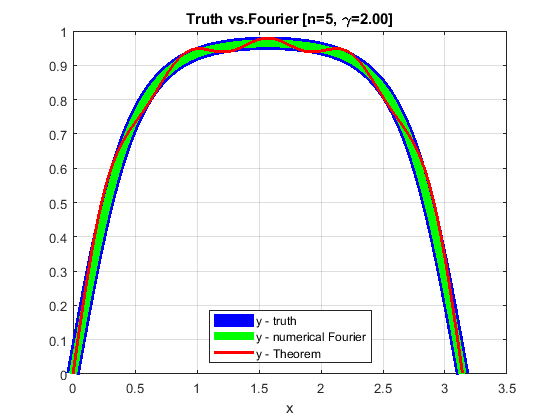

x=0:0.0001:pi;
gamma = 2;
n_max = 5;
m_max = 4;
l_max = 50;

% ==============================================================================
% Test Part 1:
% ==============================================================================
y = tanh(gamma*sin(x));

% ==============================================================================
% Test Part 2:
% ==============================================================================

% Compute the b coefs numerically using the definition of the Fourier Series
b_numerical = zeros(1,n_max);
for n = 1:n_max
    fourier_integrand = y.*sin((2*n-1)*x);
    fourier_integral = trapz(x, fourier_integrand);
    b_numerical(n) = fourier_integral;
end

% Evaluate the numerical Fourier Series
y_fourier_definition = 0;

for n = 1:n_max
    y_fourier_definition = ...
        y_fourier_definition + 2/pi*b_numerical(n)*sin((2*n-1)*x);
end

% ==============================================================================
% Test Part 2:
% ==============================================================================

% Compute the b coefs using the analytical theorem
b_theorem = zeros(1,n_max);
for n = 1:n_max
    m_sum = 0;
    for m = 1:m_max
        l_sum = 0;
        for l = 0:l_max
            q = (-1)^(m+l)*(2)^(l+1)*m^(l)/factorial(l);
            mu = MuNumerical(n,l);
            l_sum = l_sum + q*mu*gamma^l;
        end
        m_sum = m_sum + l_sum;
    end
    b_theorem(n) = 2/(2*n-1) + m_sum;
end

% Evaluate the analytical Fourier Series
y_theorem = 0;

for n = 1:n_max
    y_theorem = ...
        y_theorem + 2/pi*b_theorem(n)*sin((2*n-1)*x);
end

figure;
plot(x, y, 'linewidth', 10, 'Color', 'b');
hold on;
plot(x, y_fourier_definition, 'linewidth', 6, 'Color', 'g');
plot(x, y_theorem, 'linewidth', 2, 'Color', 'r');
grid on;
legend('y - truth', 'y - numerical Fourier', 'y - Theorem', 'location', 'south');
xlabel('x');
title_str = sprintf('Truth vs.Fourier [n=%i, \\gamma=%0.2f]', n, gamma);
title(title_str);

function mu = MuNumerical(n,l)
    x=0:0.0001:pi;
    integrand = sin((2*n-1)*x).*(sin(x).^(l));
    mu = trapz(x, integrand);
end